clc;clear;close;

%new = old - f(old)/fprime(old); newtons method

Mvals = [0, 30, 90, 135, 180, 200, 350];
evals = [.01, .1, .5, .9];

Mvlasrad = vpa(Mvals.*pi/180);

E = zeros(length(evals),length(Mvals));

for i = 1:length(evals)
    for j = 1:length(Mvlasrad)
        E(i,j) = KeplersEqNewtonsMethod(evals(i),Mvlasrad(j));
    end
end     

Edeg = E.*180/pi;

anse = sort(repmat(evals,1,length(Mvals)))';
ansM = repmat(Mvals,1,length(evals))';
ansE = reshape(Edeg',[],1);


KeplersEqNewtonsMethod(.01,30*pi/180) *180/pi;

anstable = table(ansM,anse,ansE)

anstable = 28×3 table
    ansM    anse       ansE   
    ____    ____    __________

      0     0.01    7.3635e-27
     30     0.01        30.289
     90     0.01        90.573
    135     0.01         135.4
    180     0.01           180
    200     0.01        199.81
    350     0.01         349.9
      0      0.1    1.3942e-44
     30      0.1        33.132
     90      0.1        95.701
    135      0.1        138.78
    180      0.1           180
    200      0.1        198.21
    350      0.1         348.9
      0      0.5    4.3491e-44
     30      0.5        52.827



% latextab = latex(sym([vpa(ansM),vpa(anse),vpa(ansE)]))

latextab = '\left(\begin{array}{ccc} 0 & 0.01 & 0.0000000000000000000000000073634806223197434686705805163862\\ 30.0 & 0.01 & 30.28897786495175736831697577145\\ 90.0 & 0.01 & 90.572929150344236859382363036275\\ 135.0 & 0.01 & 135.40228777521241454451228491962\\ 180.0 & 0.01 & 180.0\\ 200.0 & 0.01 & 199.80586231174126510268251877278\\ 350.0 & 0.01 & 349.89951751722429662549984641373\\ 0 & 0.1 & 1.3941690190181464031680012141333e-44\\ 30.0 & 0.1 & 33.131578685187477617546392139047\\ 90.0 & 0.1 & 95.701236174990285121566557791084\\ 135.0 & 0.1 & 138.7758307983858969691937090829\\ 180.0 & 0.1 & 180.0\\ 200.0 & 0.1 & 198.20954592601788135652896016836\\ 350.0 & 0.1 & 348.89659639404129620743333362043\\ 0 & 0.5 & 4.3490835522653452421739932003297e-44\\ 30.0 & 0.5 & 52.827087167855736993260507006198\\ 90.0 & 0.5 & 115.79362093315425852324551669881\\ 135.0 & 0.5 & 149.5278871546989307717012707144\\ 180.0 & 0.5 & 180.0\\ 200.0 & 0.5 & 193.37370290033010178376571275294\\ 350.0 & 0.5 & 340.38113495

% disp(latextab)

\left(\begin{array}{ccc} 0 & 0.01 & 0.0000000000000000000000000073634806223197434686705805163862\\ 30.0 & 0.01 & 30.28897786495175736831697577145\\ 90.0 & 0.01 & 90.572929150344236859382363036275\\ 135.0 & 0.01 & 135.40228777521241454451228491962\\ 180.0 & 0.01 & 180.0\\ 200.0 & 0.01 & 199.80586231174126510268251877278\\ 350.0 & 0.01 & 349.89951751722429662549984641373\\ 0 & 0.1 & 1.3941690190181464031680012141333e-44\\ 30.0 & 0.1 & 33.131578685187477617546392139047\\ 90.0 & 0.1 & 95.701236174990285121566557791084\\ 135.0 & 0.1 & 138.7758307983858969691937090829\\ 180.0 & 0.1 & 180.0\\ 200.0 & 0.1 & 198.20954592601788135652896016836\\ 350.0 & 0.1 & 348.89659639404129620743333362043\\ 0 & 0.5 & 4.3490835522653452421739932003297e-44\\ 30.0 & 0.5 & 52.827087167855736993260507006198\\ 90.0 & 0.5 & 115.79362093315425852324551669881\\ 135.0 & 0.5 & 149.5278871546989307717012707144\\ 180.0 & 0.5 & 180.0\\ 200.0 & 0.5 & 193.37370290033010178376571275294\\ 350.0 & 0.5 & 340.38113495327434065984

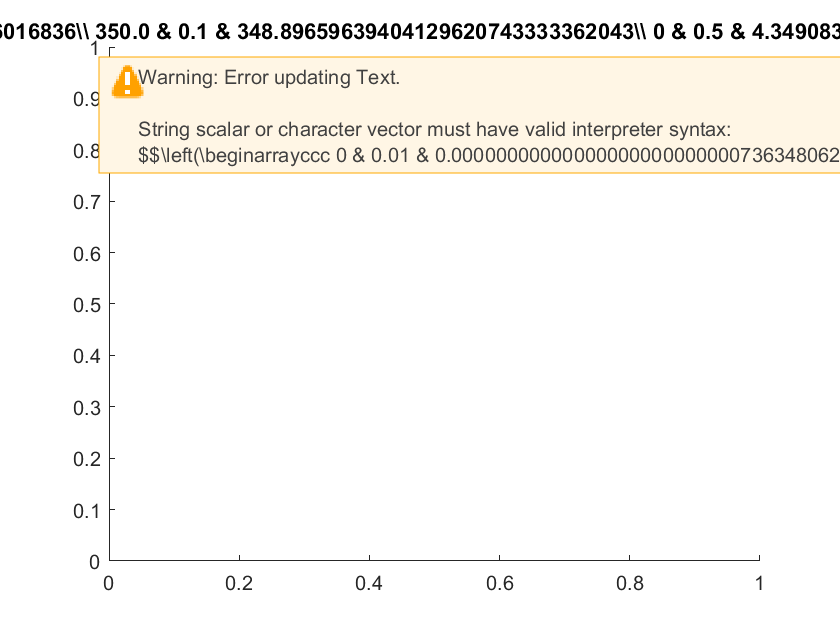

% file = fopen('answers.tex',"w+");
% fprintf(file,'%s',latextab);
% fclose(file);

function E = KeplersEqNewtonsMethod(e,M)
    if M > -pi && M < 0
        Enew = M - e;
    else % M > 0
        Enew = M + e;
    end
    
    error = 1; %this is so that the error is initial outside the tolerenace and is imediatly overwritten
    while error >= 1e-6
        Eold = Enew;
        Enew = Eold + (M-Eold + e*sin(Eold)) / (1-e*cos(Eold)); % for kepelers eq newtons method is
        error = abs(Enew - Eold);
    end
    
    E = Enew;
end
